# TP pression de vapeur saturante

## Liste des fonctions Matlab utilisées :

## **Calcul de l'incertitude sur la pente**

### **Principe**

On considère la série de 4 points de coordonnées (X,Y) suivants définis avec leurs incertitudes dx et dy qui dépendent de chaque point. La droite de régression linéaire est tracé en noir. Pour les 4 points on fait un tirage aléatoire de coordonnées (x,y) dans la boite dx.dy (en suivant une loi normale). On cherche alors la courbe de tendance de cette série de points, puis on recommence $n$-fois (en pratique avec $n=50$ on obtient un résultat plutôt reproductible. Il reste ensuite à calculer l'écartype sur les $n$ pentes. Selon la définition que l'on prend pour $dx$ et $dy$, i.e. représente 1, 2 ou 3 fois l'écartype de la distribution, on calculera 1, 2 ou 3 fois l'écart-type sur la distribution de pente.

Les figures ci-dessous représentent à gauche un exemple simplifié avec $n=3$ sur lequel on a représenter les points et les 3 courbes de tendance avec en noir la courbe de tendance des points expérimentaux, et à droite un exemple avec un tirage de $n=60$, sans représenter les courbes de tendances.

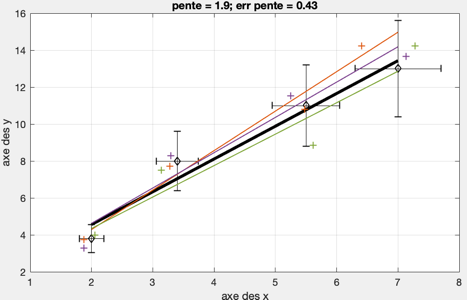   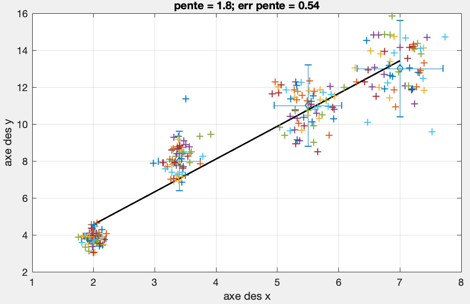

### **Fonction utilisateur (à placer dans le répertoire travail Matlab)**

Pour mettre en oeuvre la technique proposée ci-dessus, nous avons défini la fonction "err_pente" qui esttime l'erreur par méthde dite de Monte Carlo.

## Entrée des Données

Plusieurs méthodes peuvent-être utilisées :

- Lecture d'un fichier texte ou Tableur (Excel, LibreOffice Calc...)

- Copy/paste à partir de données d'un tableur

- Entrée directement dans une variable "table" de Matlab

Dans tous les cas il est pratique de rentrer les données dans une variable de type "table" qui permet de stocker des données en colonnes en ajoutant sur la première ligne du texte de description de ces colonnes.

### (1) Lecture d'un fichier texte ou Tableur 

 L'import de données depuis un **fichier Excel** par ligne de commande est très simple, notamment si on passe par la création d'une "**table**" dans Matlab. Supposant que les données sont dans un fichier excel qui aurait le nom 'data_cp.xlsx', qui pourrait comporter plusieurs feuilles dont celle contenant les données s'appellerait 'Cp_val' et serait dans les colonnes B1:F48, la fonction serait 

Evidemment si le classeur ne contient qu'une feuille avec seulement les données que l'on cherche, les paramètre 'sheet' et 'range' sont inutiles.

### (2) Copy/paste à partir de données d'un tableur

Il suffit de cliquer dans la fenêtre "workspace" de Matlab sur le petit triangle, ce qui ouvre un masque d'import de données (cf figure), et de se laisser guider. Si par exemple on a collé deux colonnes des données $T$ et $C_p$ on peut leur donner les noms T et Cp_O2 et choisir dans "Output type" "column vectors", si l'on veut importer chaque liste de quantité dans une variable individuelle (cf ci-dessous)

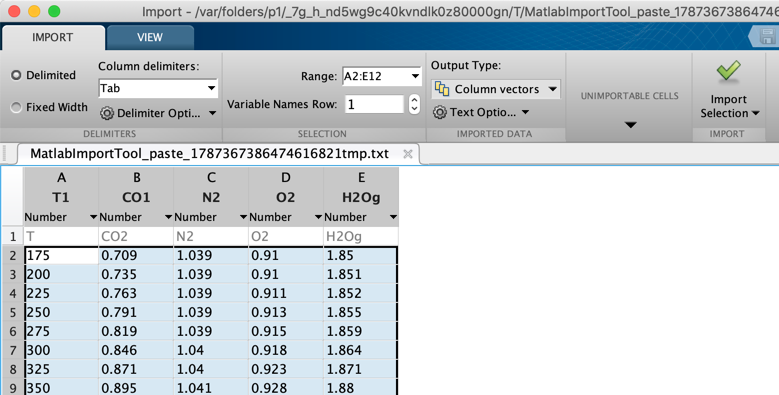

Il peut également être pratique d'importer les données dans une variable de type "table", ce qui permet de mélanger les titres dans la première ligne et les données dans les autres. Cela permet notamment d'explorer les valeurs ou de les vérifier, avant de transférer les données dans desvecteurs colonnes individuels. 

### (3) Entrée directement dans une variable "table" de Matlab

En imaginant que l'on souhaite rentrer les données dans une table dont le nom est "manip_1" et qui comporte deux colonnes, il suffit de taper dans la fenêtre de commande : 

Cela crée la variable dans le workspace, et il suffit de cliquer dessus pour pouvoir l'éditer dans un mini-tableur et de rentrer les données.

Il est intéressant de noter que dans ce dernier cas où l'on rentre les données à la main, elles ne sont pas sauvé et il peut être intéressant de sauvergarder el workspace, ce qui permet de retrouver à tout moment ces données.

## Application au TP Pression de vapeur saturante

Pour tester ce TP, on considère que toutes les données ont été rentrées dans variables de type  Table, intitulées manip1 manip2 et manip3. Elles sont contenues dans le fichier "thermo_TP_matlab_2020.mat" à placer dans le répertoir de travail de Matlab.

load('thermo_TP_matlab_2020.mat');  %Charge les variables nécessaires pour tester le fichier

### 1. Méthode 1

On enregistre une variation de pression $\Delta P$ en fonction de la température $T$

la pression dans la pièce est : $P_o=1022\,\mathrm{hPa}$

%----- partie 1--------

Po=1022e2;  % pression atmosphérique
R=8.314;
M_eau=18;   % en g
T=table2array(manip1(:,1));  % transformer les données depuis Table dans array (vecteur numérique)
P=table2array(manip1(:,2))+Po;
l=length(T);    % longueur  vecteur T
DP=2*1000*ones(l,1);  %erreur sur y en absolu
erry=DP./P;  % erreur sur ln(P)
DT=ones (l,1);
errx=-DT./T.^2;
X=1./T; Y=log(P); 


% tracé courbe 1/T - log(P) avec barres d'erreur
errorbar(X,Y,erry,erry,errx,errx,'d','MarkerSize',6,'CapSize',10,'MarkerFaceColor','k')
xlabel('1/T (K^{-1})')
ylabel('ln P*')
title('1/T - ln P^*')
grid on
hold on
p = polyfit(X,Y,1); % ajustement courbe
y=polyval(p,X);          % calcul des points fit pour tracé
plot(X,y,"Color",'k')    % tracé de la courbe ajustée
hold off


[a b]=err_pente(X,Y,errx,erry,50,1); % ca
DvapH=a*R; fprintf('DvapH = %1.2f kJ/mol',DvapH/1e3)

DvapH = -39.34 kJ/mol

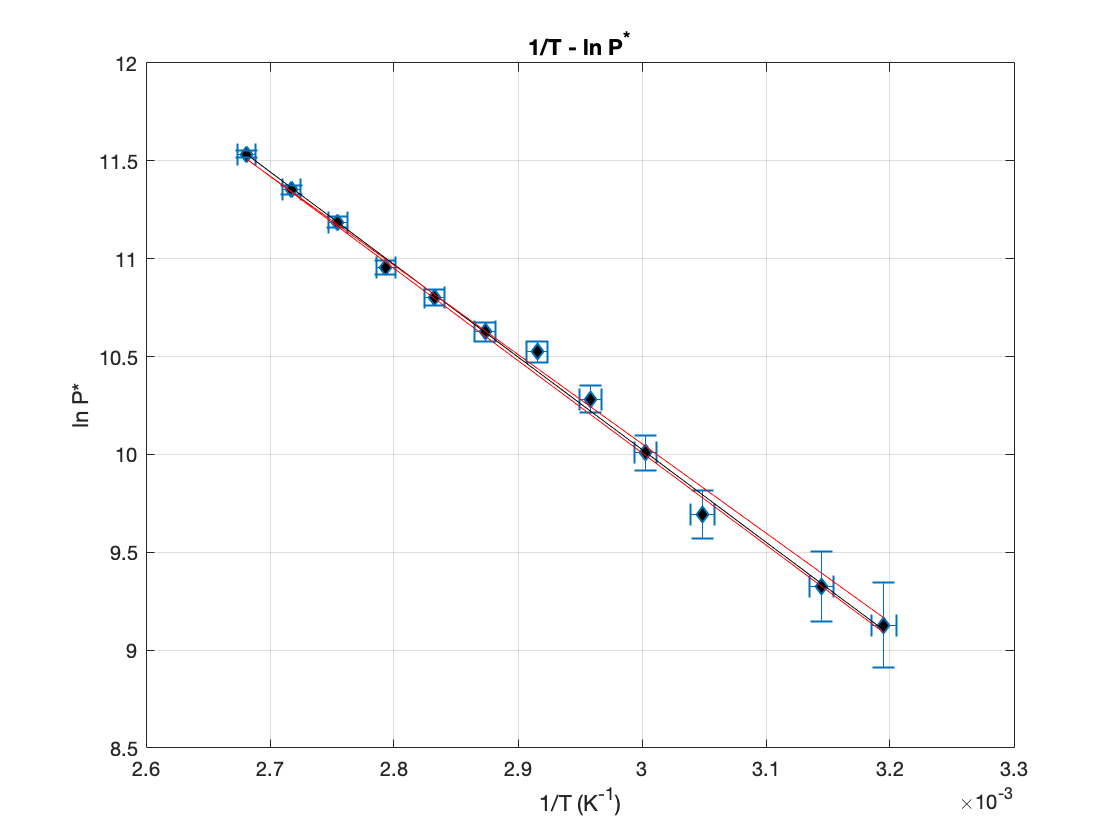

D_DvapH = 2.32 kJ/mol

D_DvapH=b*R; fprintf('D_DvapH = %1.2f kJ/mol',D_DvapH/1e3)

On trouve finalement une enthalpie molaire de vaporisation  est : $\Delta_{vap}\bar H=-39.3\pm 1.7\,\mathrm{kJ.mol^{-1}$

### 2. Méthode 2

#### 2.1 manip n°2


%------ partie 2 ----------
% Données du problème :

m=399.3;  % masse d'eau en g
mu=7;      % calorimètre en g
cp_eau=4.18; % Cp eau en J/g

% récupération données expérimentales
time=table2array(manip2(:,1));
Temp=table2array(manip2(:,2));
l=length(time);
Dtime=0.5*ones(l,1); DTemp=1*ones(l,1);   %incertitudes (sous forme matrice)

Récupération des données :

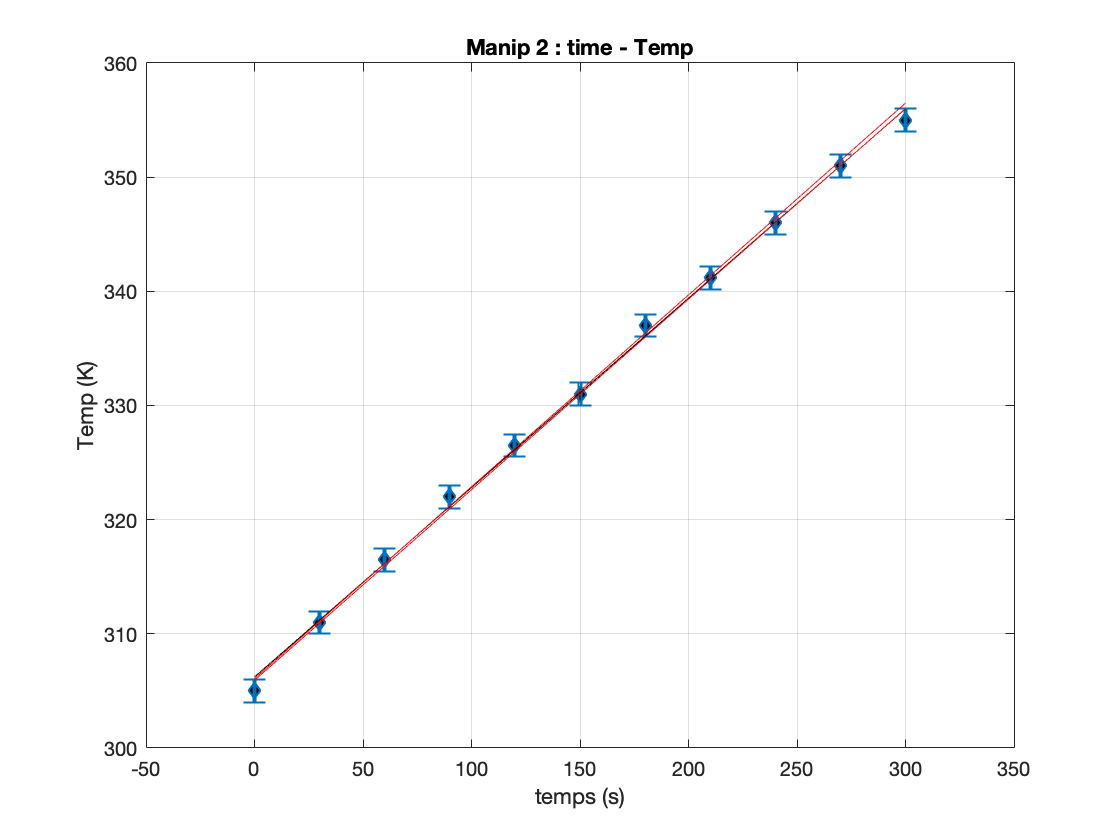

%tracé courbe
errorbar(time,Temp,DTemp,DTemp,Dtime,Dtime,'d','MarkerSize',6,'CapSize',10,'MarkerFaceColor','k')
xlabel('temps (s)')
ylabel('Temp (K)')
title('Manip 2 : time - Temp')
grid on; hold on;

p = polyfit(time,Temp,1); % ajustement courbe
y=polyval(p,time);          % calcul des points fit pour tracé
plot(time,y,"Color",'k')    % tracé du fit moyen
hold off

[a b]=err_pente(time,Temp,Dtime,DTemp,50,2); % calcul incertitudes


Puis=(m+mu)*cp_eau*p(1);fprintf('Puis = %1.f W',Puis)   %Puissance

Puis = 282 W

DPuis=Puis*(mu/(mu+m)+(b)/p(1)); fprintf('DPuis = %1.1f W',DPuis)  % incertitude

DPuis = 10.8 W

#### 2.2 manip n°3


%----- manip3---------- 

time=table2array(manip3(:,2));  % transformer les données depuis Table dans array (vecteur numérique)
m=table2array(manip3(:,1));  
Temp=table2array(manip3(:,3));
l=length(time)

l = 23

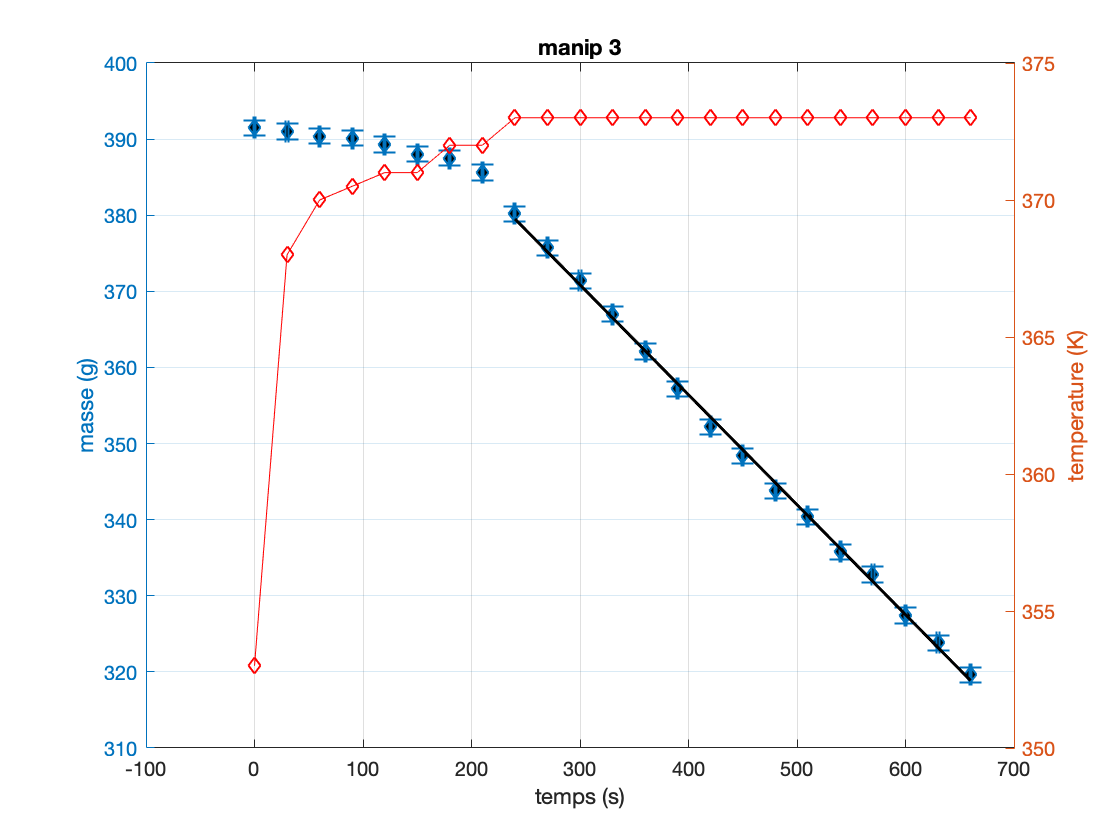

Dm=1*ones(l,1); %incertitudes sur m
Dtime=1*ones(l,1);  %incertitudes sur time

%--- tracé des courbes ----

figure
yyaxis left   % axe des y à gauche
errorbar(time,m,Dm,Dm,Dtime,Dtime,'d','MarkerSize',6,'CapSize',10,'MarkerFaceColor','k')
xlabel('temps (s)')
ylabel('masse (g)')
%text(5.5,150,'\leftarrow 3x^2log(x)','FontSize',16)
hold on
yyaxis right  % axe des y à droite
plot(time,Temp,'-d','color','r')
ylabel('temperature (K)')
xlabel('temps (s)')
title('manip 3')
grid on

% extraction des données linéaires et tracé droite tendance sur courbe
t_an=time(9:end);
m_an=m(9:end);
Dt_an=Dtime(9:end);
Dm_an=Dm(9:end);

p = polyfit(t_an,m_an,1); % ajustement courbe
y=polyval(p,t_an);   
yyaxis left
plot(t_an,y,"Color",'k','LineWidth',1.5) % tracé courbe de tendance

[a b]=err_pente(t_an,m_an,Dm_an,Dt_an,50,2); % calcul incertitudes

hold off


DvapH=Puis/(a/M_eau); fprintf('DvapH = %1.1f kJ/mol',DvapH/1e3)

DvapH = -35.1 kJ/mol

DDvapH=(DPuis/Puis+b/a)*DvapH; fprintf('DDvapH = %1.1f kJ/mol',DDvapH/1e3)

DDvapH = -0.5 kJ/mol